# Figuras exploratorias para ONI, SOI y MEI

## Para ONI

El Niño has an ONI value greater than or equal to 0.5 that persists for at least five months, with a maximum value during the event that is greater than or equal to 1.0. Similarly, a La Niña has an ONI value less than or equal to –0.5 that persists for at least five months, with a minimum value during the event that is less than or equal to –1.0.

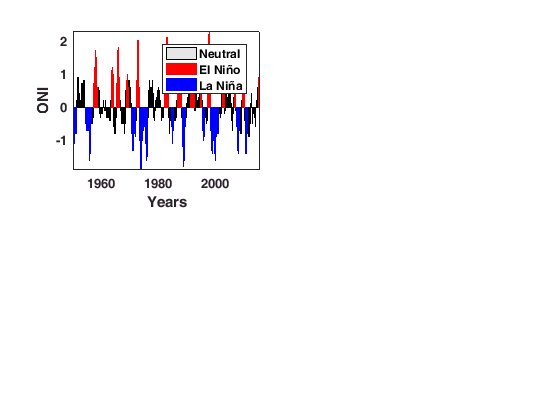


load ONI

pen=oniTbl.oni>=0.5; %Values larger than 0.5

ens=diff(find(diff(pen))); %identifies length of sequences, but not the
% first one, nor the last one, so we build a fast cycle that does that

a=0;
j=0;
while a==0;
    j=j+1;
    a=pen(j);
end
ens=[j-1;ens];
ens=[ens;length(pen)-sum(ens)];


j=1;
pen2=zeros(length(pen),1);
for i=1:length(ens)
    if ens(i)>=5
        if ~mod(i,2)==1%this is when the group is made of true values
            if max(oniTbl.oni(j:j+ens(i)-1))>=1
                pen2(j:j+ens(i)-1)=1;
            end
        end
    end
    j=sum(ens(1:i))+1;
end
pen2=logical(pen2);



% La Niña
pln=oniTbl.oni<=-0.5; %Values under 0.5

lns=diff(find(diff(pln))); %identifies length of sequences, but not the
% first one, nor the last one, so we build a fast cycle that does that

a=1;
j=0;
while a==1;
    j=j+1;
    a=pln(j);
end
lns=[j-1;lns];
lns=[lns;length(pen)-sum(lns)];

j=1;
pln2=zeros(length(pln),1);
for i=1:length(lns)
    if lns(i)>=5
        if mod(i,2)==1%this is when the group is made of true values
            if min(oniTbl.oni(j:j+lns(i)-1))<=-1
                pln2(j:j+lns(i)-1)=1;
            end
        end
    end
    j=sum(lns(1:i))+1;
end
pln2=logical(pln2);

subplot 221
bar(oniTbl.datenum, oniTbl.oni,'FaceColor',[.9 .9 .9],'EdgeColor','k')
hold on
bar(oniTbl.datenum(pen2), oniTbl.oni(pen2),'r', 'EdgeColor','r'), hold on
bar(oniTbl.datenum(pln2), oniTbl.oni(pln2),'b','EdgeColor','b')

legend('Neutral','El Niño', 'La Niña')
datetick('x','yyyy')
axis tight
xlabel 'Years'
ylabel 'ONI'

hold off

## Para SOI

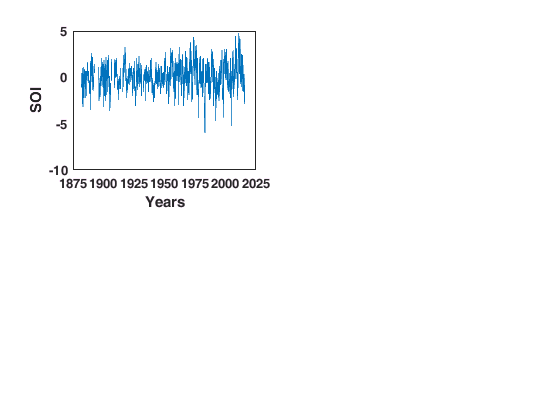

load SOI %Cargar SOI

plot(soiTbl.datenum, soiTbl.soi) %Graficar SOI contra datenum
datetick('x','yyyy') %Especificar que el eje es una fecha
xlabel 'Years' %Nombrar eje x 
ylabel 'SOI' %Nombrar eje y

## Para MEI

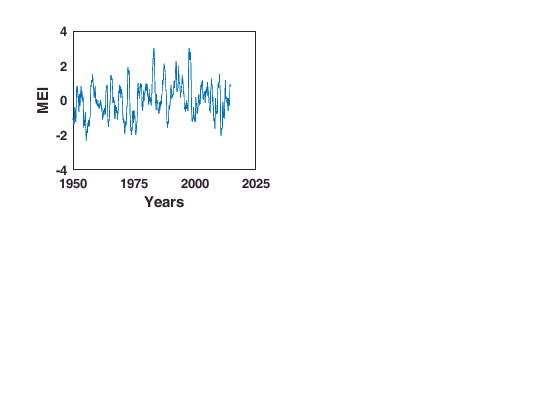

meiTbl = readtable('MEI_mensual.csv');

meiTbl.datenum = datenum(meiTbl.Year, meiTbl.Month, 1);

plot(meiTbl.datenum, meiTbl.Mei)
datetick('x','yyyy')
xlabel 'Years'
ylabel 'MEI'